**Extract plot directly from Comsol using COMSOL Multiphysics LiveLink for MATLAB **

mphtags -show

Unrecognized function or variable 'mphtags'.

%%Remove model if there is any model before
%ModelUtil.remove('Model') %Remove model

#### Open the mph file in matlab and launch model in Comsol:

filename = ['C:\Users\vanan\OneDrive\Desktop\Pit Propagation Model\Single Pit Growth\pcpSingle_v1_out'];
mphopen(filename);

The COMSOL model is now accessible using the variable 'model'


mphlaunch; %Open comsol desktop file

#### Get model parameters:

model_param = mphgetexpressions(model.param) %Export model parameters

model_param = 36×5 cell array
    {'dMe'       }    {'0.72e-5[cm^2/s]' }    {'Diffusion coefficient, Me2+. Ref 1'                                                                           }    {[7.2000e-10]}    {'m^2/s'  }
    {'dNa'       }    {'1.334e-5[cm^2/s]'}    {'Diffusion coefficient, Na+. Ref 1'                                                                            }    {[1.3340e-09]}    {'m^2/s'  }
    {'dCl'       }    {'2.032e-5[cm^2/s]'}    {'Diffusion coefficient, Cl-. Ref 1'                                                                            }    {[2.0320e-09]}    {'m^2/s'  }
    {'zMe'       }    {'2.2'             }    {'Charge number of Metal/ Alloys'                                                                               }    {[    2.2000]}    {0×0 char }
    {'zNa'       }    {'1'               }    {'Charge number of Na+'                                                                                         }    {[         1]}    {0×0 char }
    {

**Get initial geometry from the model**

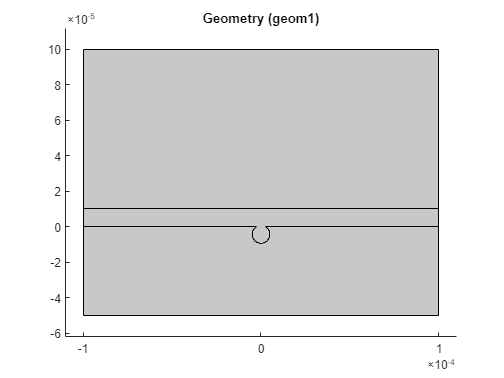

mphgeom(model,'geom1')

**Export plot from Comsol**

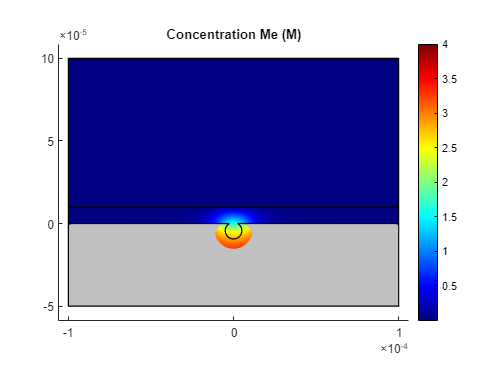

% cMe Concentration
mphplot(model,'pg32','rangenum',1);

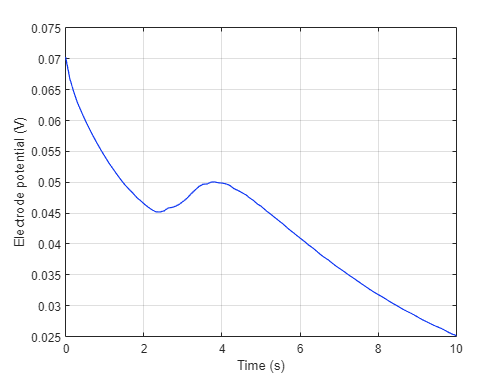

%% Plot electrode potential vs time
mphplot(model,'pg33');